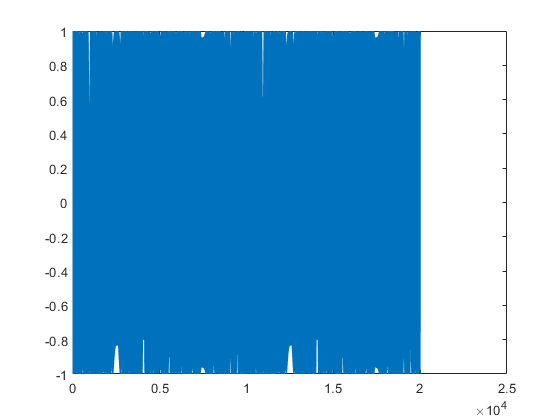

max_time = 2;
fs = 10e3; 
noise_weight = 0.5;
t = 0:1/fs:max_time; 
x = vco(sin(2*pi*t),[0.1 0.4]*fs,fs);
size = length(t);
noise = rand(1,size)*noise_weight;

noisy_signal = x + noise;

filtSpec.range = [1000 4999];
filtSpec.order = floor(fs*4/3000)+1;
filtPts = fir1(filtSpec.order, 2/fs*filtSpec.range);

filtered_signal = filter(filtPts, 1, noisy_signal, [], 2);
figure(1)
plot(x);

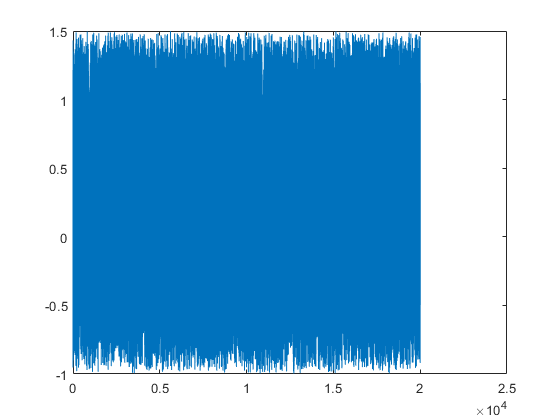

figure(2)
plot(noisy_signal);

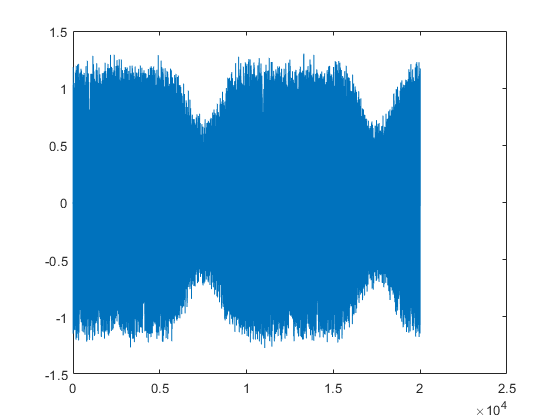

figure(3)
plot(filtered_signal);

[upper, lower] = envelope(filtered_signal);
figure(4)
demodulated = filtered_signal./upper

demodulated =     0.0756    0.0208   -0.0632   -0.1323   -0.5731   -0.5898   -0.2590    0.9999   -0.1210   -0.9788    0.0704    0.9971   -0.0572   -0.9779   -0.1601    0.9887    0.0955   -0.9793   -0.0473    0.9992    0.0247   -0.9797    0.0215    0.9978   -0.1314   -0.9600    0.1939    0.9912   -0.0986   -0.9755    0.1806    0.9879   -0.0385   -0.9813    0.0533    0.9888   -0.2216   -0.9442    0.2336    0.9781   -0.2420   -0.9216    0.4535    0.8641   -0.5027   -0.8278    0.5794    0.8491   -0.3460   -0.9349


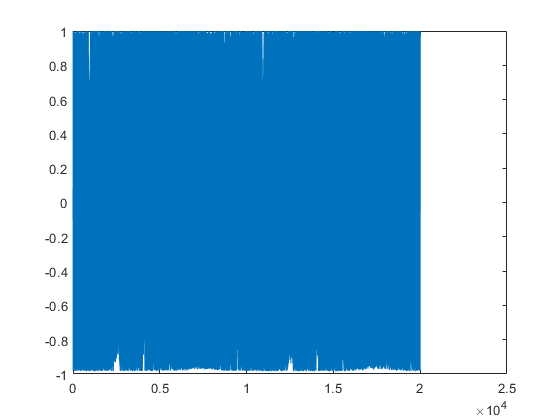

plot(filtered_signal./upper);




R = eye(p);

for n_source = 1:size-p
    n = n_source + p
    H_t = demodulated(1,n-p:n-1);
    
    Sigma_r = ()
    
    R = R + c(Sigma_r - R);
    
    K_n = P_prior * H' * (( H*P_prior*H' + trace(R) * 1 ) ^ -1);
end
filtered


% p = 100;
% sigma_w = 0.005;
% sigma_v = 0.05;
% var_w = noise_weight;
% Sigma_w = eye(p) * sigma_w;
% Sigma_v = eye(p) * sigma_v;
% yule_args = aryule(demodulated, p);
% 
% x_given_n = yule_args(1);
% Sigma_x_given_n = diag(yule_args(2:length(yule_args)));
% % demodulated = [zeros(1,p) demodulated]
% 
% for n_source = 1:size-p
%     n = n_source + p;
%     C = flip(demodulated(1,n-p:n-1));
%     
%     % x_given_n n | n - 1 is the same as n | n
%     Sigma_x_given_n = Sigma_x_given_n + Sigma_w; % update Sigma_x_given_n to n | n - 1
%     
%     y = flip(demodulated(1,n+1-p:n)); % get the input for current value of y
%     y_given_n = C * x_given_n; % update y_given_n to n | n - 1
%     sigma_y = C * Sigma_x_given_n * C' + sigma_v; % update sigma_y to n | 1
%     
%     
%     K = Sigma_x_given_n*C'*(sigma_y^-1);
%     x_given_n = x_given_n + K'*(y' - y_given_n'); % update x_given_n
%     Sigma_x_given_n = Sigma_x_given_n - (K' * sigma_y * K);  % update Sigma_x_given_n
%     filtered(n_source) = x_given_n;
% end
% filtered

filtered =    -4.1816    0.2751    0.1177   18.3097    0.6380   -1.7154    1.5918   -0.2812    0.6625   -5.8504    0.8157   -0.4285    0.6169   -4.4386    0.9717   -0.2330    0.0839  -59.5328    0.7366   -0.3674   -0.1130   31.9540    0.5500   -0.5992   -0.5099    6.5656    0.5119   -0.4720   -1.2049    3.1482    0.3631   -0.7930   -0.9690    3.4505    0.4081   -0.4171   -3.1191    1.7111    0.2876    0.1264   17.7731    1.1693    0.0801   -0.5916  -20.5540    1.0816    0.0657    0.9177   11.7538    1.0264


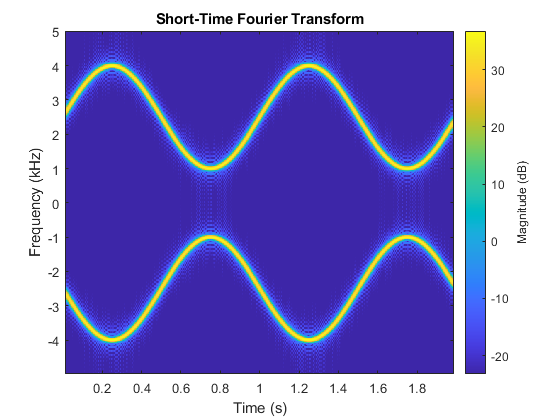


% yv = demodulated;
% +
% P = B*Q*B';         % Initial error covariance
% x = zeros(3,1);     % Initial condition on the state
% ye = zeros(length(t),1);
% ycov = zeros(length(t),1); 
% 
% for i = 1:length(t)
%   % Measurement update
%   Mn = P*C'/(C*P*C'+R);
%   x = x + Mn*(yv(i)-C*x);   % x[n|n]
%   P = (eye(3)-Mn*C)*P;      % P[n|n]
% 
%   ye(i) = C*x;
%   errcov(i) = C*P*C';
% 
%   % Time update
%   x = A*x + B*u(i);        % x[n+1|n]
%   P = A*P*A' + B*Q*B';     % P[n+1|n]
% end



stft(x,fs,'Window',kaiser(256,5),'OverlapLength',220,'FFTLength',512)

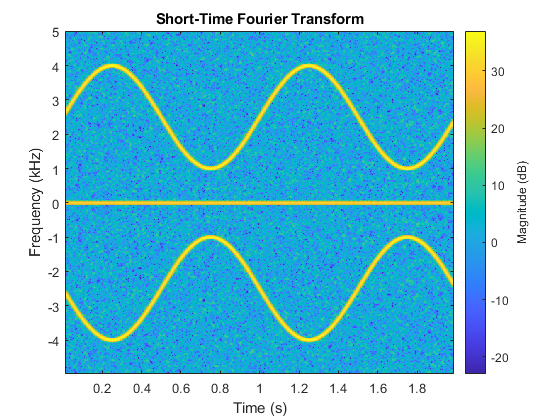

stft(noisy_signal,fs,'Window',kaiser(256,5),'OverlapLength',220,'FFTLength',512)

stft(filtered,fs,'Window',kaiser(256,5),'OverlapLength',220,'FFTLength',512)

Error using stft
Expected X to be finite.

Error in signal.internal.stft.stftParser>verifyDataAndTime (line 316)
        validateattributes(x,{'single','double'},...

Error in signal.internal.stft.stftParser (